# Fitting a Line

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads and plots the data.

data = readtable("data\data.xlsx", Sheet="data");
dataTrain = readtable("data\data.xlsx", Sheet="dataTrain");
dataTest = readtable("data\data.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           200x2              4387  table              
  dataTest        60x2              2147  table              
  dataTrain      140x2              3427  table              



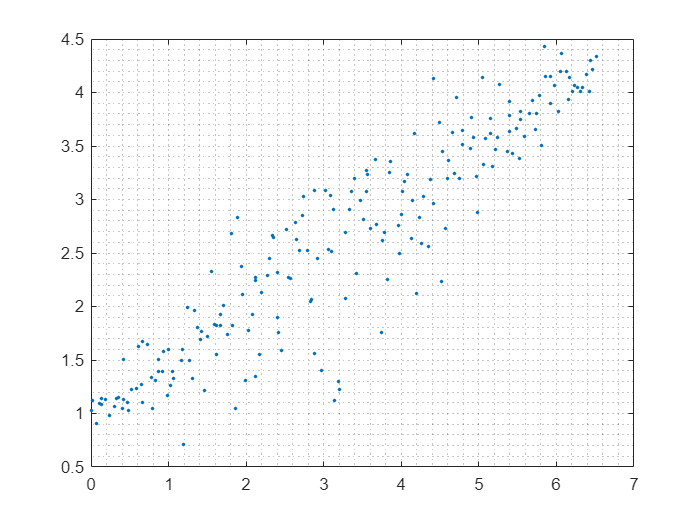

plot(data.x, data.y, ".")
grid minor

## Task 1

The table `data` has been split into a training set, `dataTrain`, and a test set, `dataTest`.

You can create a linear regression model using the following syntax:

`mdl` `=` `fitlm``(``trainingData``)`

mdl = fitlm(dataTrain);

## Task 2

You can use the `predict` function to predict the response on your test data.

`predictions` `=` `predict``(``linearMdl``,``testData``)`

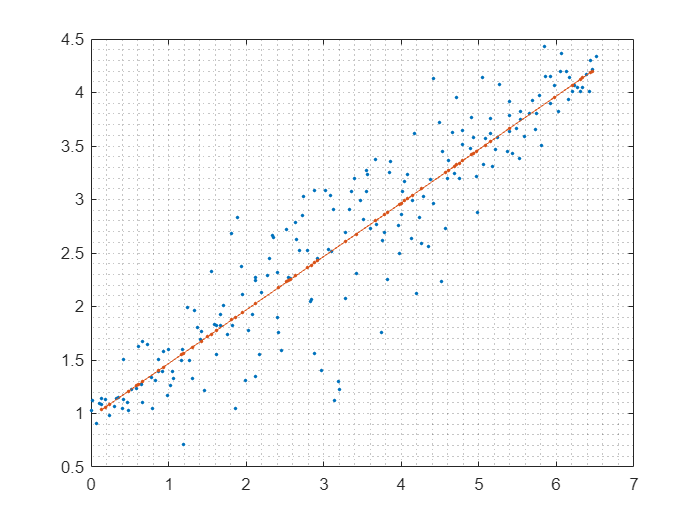

yPred = predict(mdl, dataTest);

hold on
plot(dataTest.x, yPred, ".-")
hold off